# Toy Experiments

MATLAB results don't give the linear operator on the regressand. So we have to do the estimation by hand.

## DGP

Adapted from Hastie & Tibshirani, p 12. $Y = \sin(\pi X)+\epsilon$

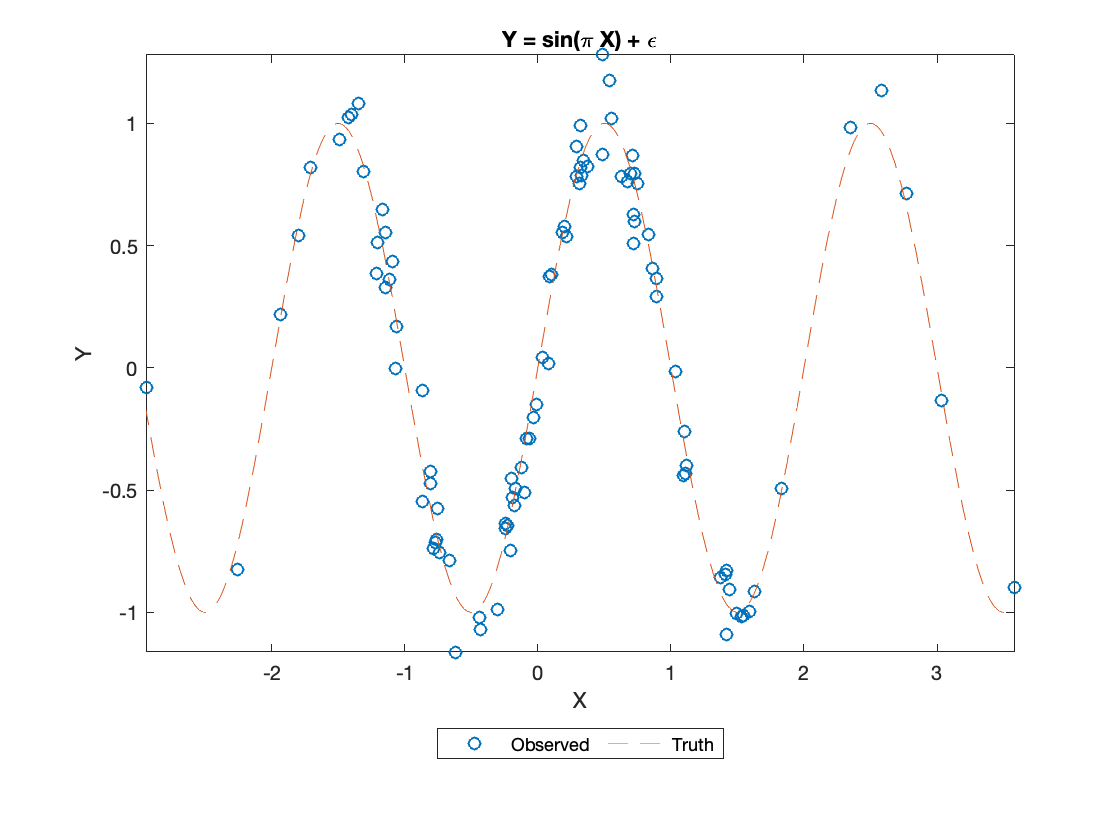

rng default; % For testing

n = 100;
k = 1;

X = normrnd(0,1,n,k);
X = sort(X);
epsilon = normrnd(0,1/9,n,k);
Y = sin(pi*X)+epsilon;
save('dgp.mat','X','Y');

y_limits = [min(Y) max(Y)];
plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x),'--');
xlim([X(1) X(end)]);
ylim(y_limits);
title('Y = sin(\pi X) + \epsilon');
legend('Observed', 'Truth','Location','bestoutside',...
    'Orientation','horizontal');
xlabel('X');
ylabel('Y');
hold off;

## Smoothness Measures

varNames ={'df_Px','df_Err', 'df_Var', 'df_Mx', 'cond'};
rowNames = {'linear','affine','NW','LL','regSpline',...
    'smoothSpline','interp'};
s_rows = size(rowNames,2);
s_cols = size(varNames,2);
smoothness = table('Size',[s_rows s_cols],'VariableTypes',...
    [repmat("double",1,s_cols)],'VariableNames',varNames,...
    'RowNames',rowNames);

## OLS

### Linear


$$m = X(X'X)^{-1}X'Y$$


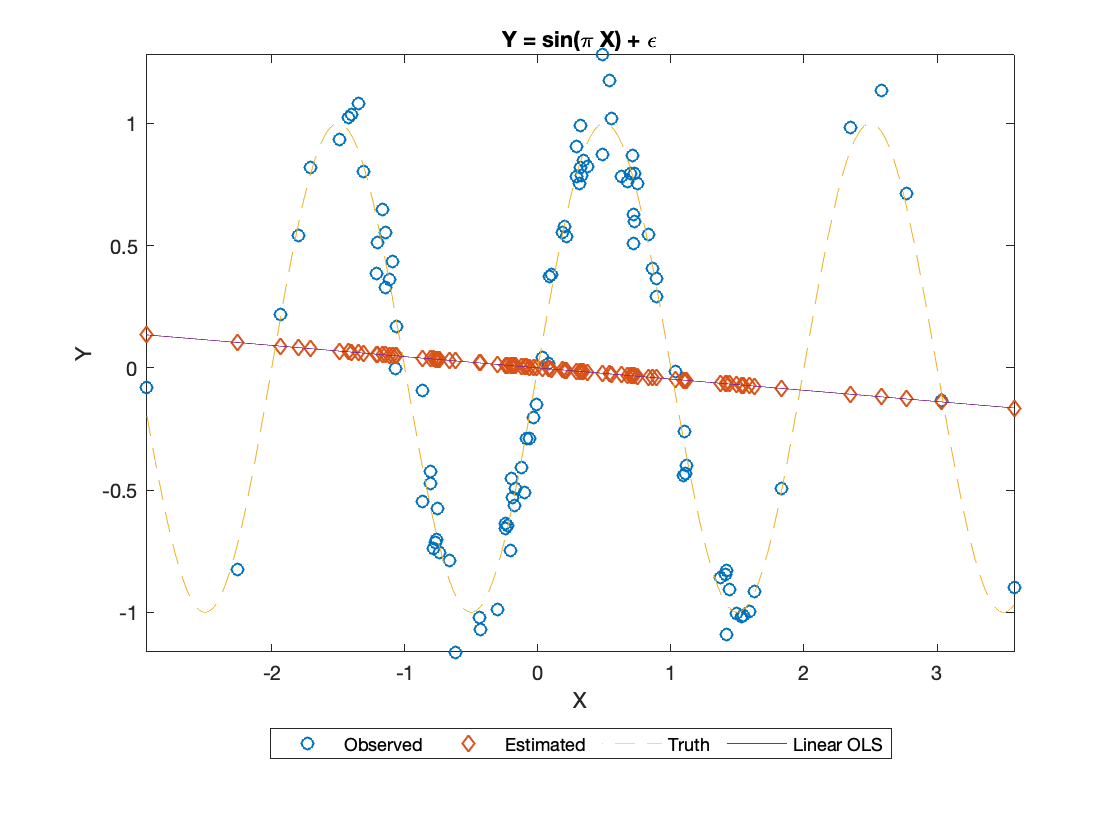

[n k] = size(X);
lo = X*(X'*X)^-1*X';
Y_lo = lo*Y;
beta_lo = (X'*X)^-1*X'*Y;

xx = X(1):0.01:X(n);
yy = beta_lo*xx;

y_limits = [min(min(Y),min(Y_lo)) max(max(Y),max(Y_lo))];
plot(X,Y,'o',X,Y_lo,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated','Truth','Linear OLS',...
    'Location','bestoutside','Orientation','horizontal');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,lo,rowNames(1));

### Affine


$$m = [\mathbf{1_n} \enspace X]([\mathbf{1_n} \enspace X]'[\mathbf{1_n} \enspace X])^{-1}[\mathbf{1_n} \enspace X]'Y$$


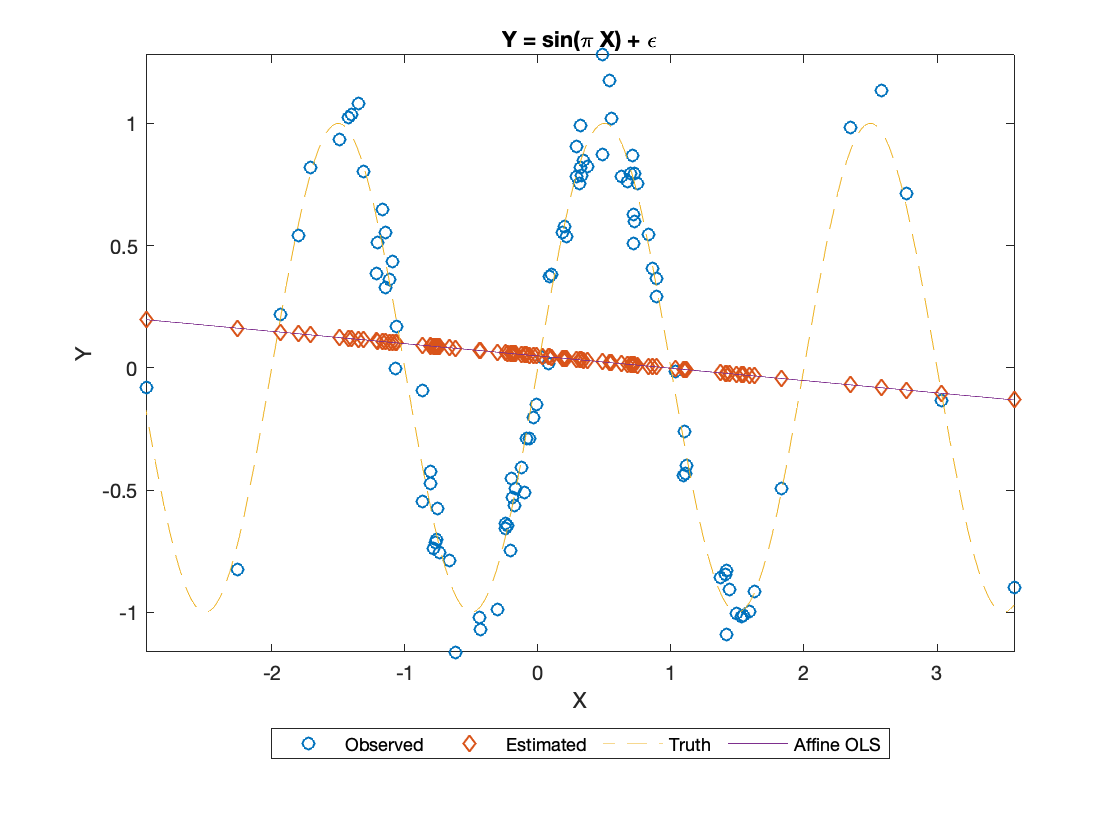

[n k] = size(X);
affineX = [ones(n,1) X];
ao = affineX*(affineX'*affineX)^-1*affineX';
Y_ao = ao*Y;
beta_ao = (affineX'*affineX)^-1*affineX'*Y;

xx = X(1):0.01:X(end);
yy = beta_ao(2)*xx+beta_ao(1);

y_limits = [min(min(Y),min(Y_ao)) max(max(Y),max(Y_ao))];
plot(X,Y,'o',X,Y_ao,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated','Truth','Affine OLS',...
    'Location','bestoutside','Orientation','horizontal');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,ao,rowNames(2));

## Kernel-Based Estimators

Bandwidth choice

h=1;

### Nadaraya-Watson


$$\hat{m}(x_0) = \frac{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)y_l}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)}$$
 

$\hat{Y}_{NW} = KY$, with elements $k_{i,j} = \frac{k\Big(\frac{x_j-x_i}{h}\Big)}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_i}{h}\Big)}$ 

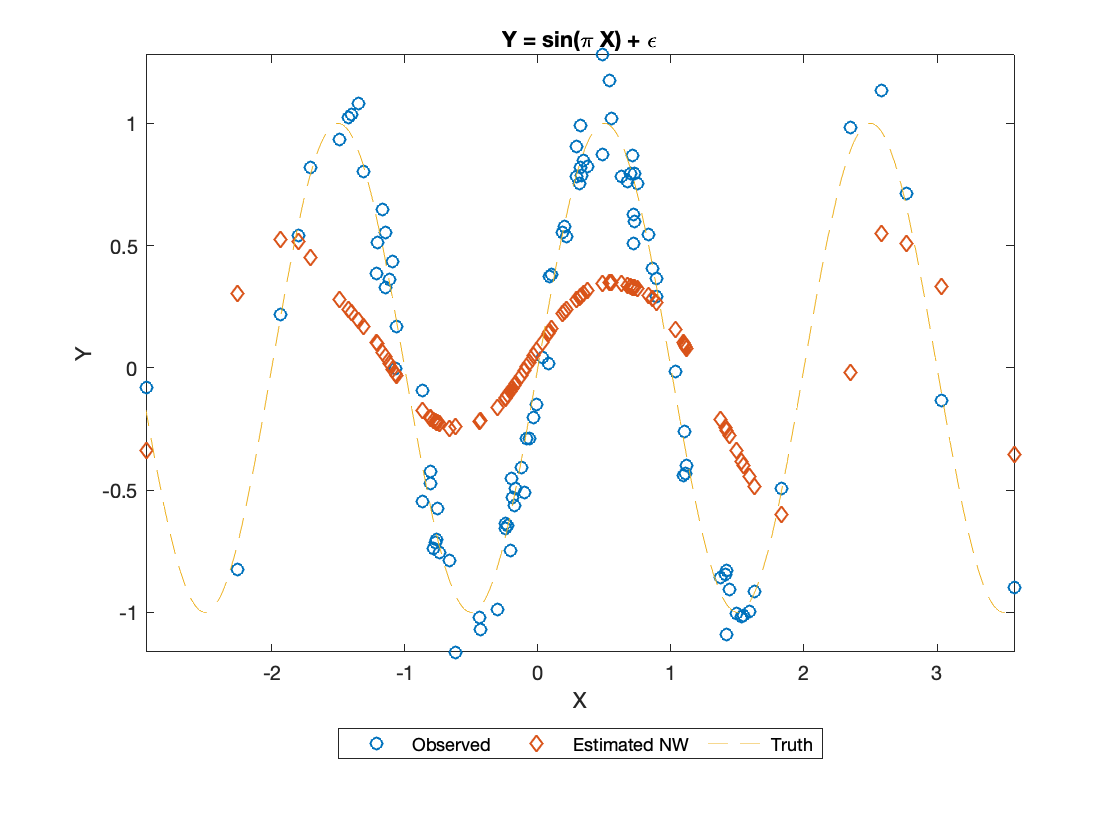

[n, k] = size(X);
% diff_ij = (x_j-x_i)/h
diff = (repmat(X',n,k)-repmat(X,k,n))/h;
%Epanechnikov kernel
numerator = 3/4*(ones(n*k)-diff.^2).*(abs(diff)<=1);
denominator = repmat(sum(numerator,2),k,n);
K = numerator./denominator;

Y_NW = K*Y;

y_limits = [min(min(Y),min(Y_NW)) max(max(Y),max(Y_NW))];
plot(X,Y,'o',X,Y_NW,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated NW','Truth',...
    'Location','bestoutside','Orientation','horizontal');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,K,rowNames(3));

### Local Linear

$\tilde{m}(x_0) = [\mathbf{1_n} \enspace X_0]\big([\mathbf{1_n} \enspace X_0]'W_0[\mathbf{1_n} \enspace X_0]\big)^{-1}[\mathbf{1_n} \enspace X_0]'W_0Y$, where $X_0 = [X-x_0\mathbf{1_n} ]$ and $W_0 = diag[k\Big(\frac{x_1-x_0}{h}\Big), ... ,k\Big(\frac{x_n-x_0}{h}\Big)]$ 

$\hat{Y}_{LL} = LY$, with row i given as the i'th row of $[\mathbf{1_n} \enspace X_i]\big([\mathbf{1_n} \enspace X_i]'W_i[\mathbf{1_n} \enspace X_i]\big)^{-1}[\mathbf{1_n} \enspace X_i]'W_i$

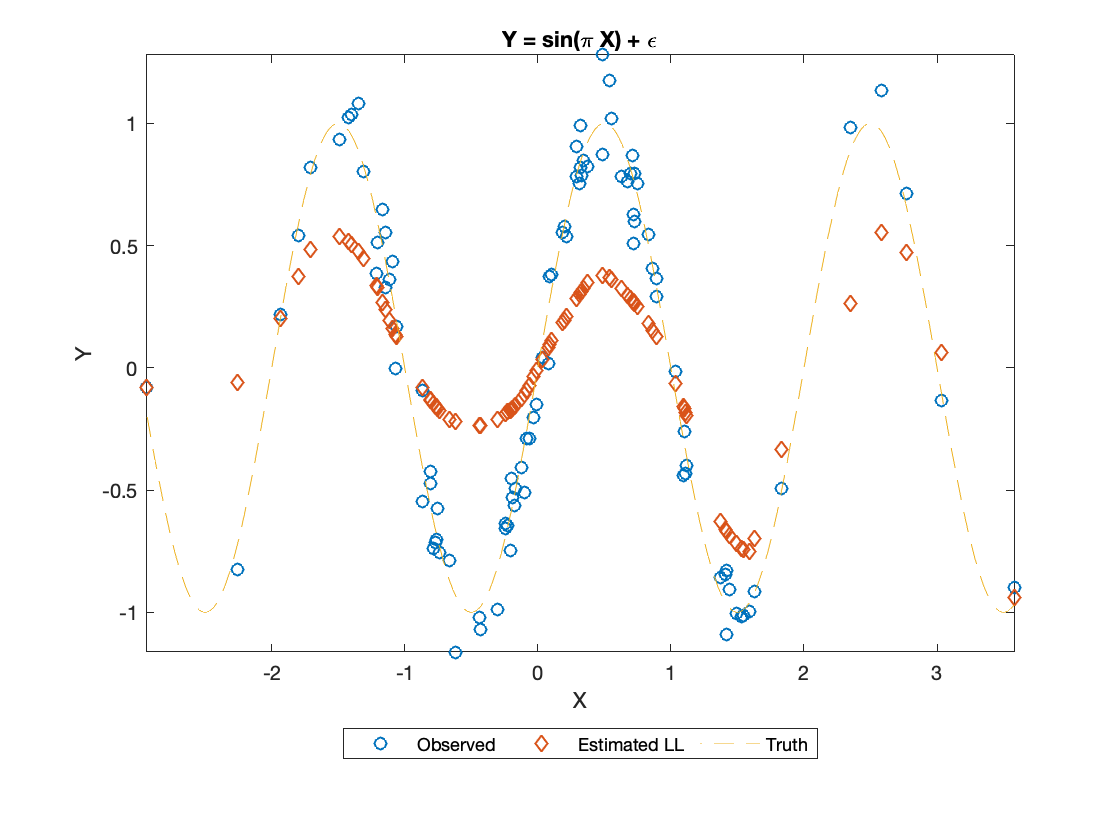

[n, k] = size(X);
L = zeros(n,n);

% diff_ij = (x_j-x_i)
diff = (repmat(X',n,k)-repmat(X,k,n));
%Epanechnikov kernel
kn = 3/4*(ones(n*k)-(diff/h).^2).*(abs(diff./h)<=1);
nOnes = ones(n,1);
for i=1:n
    x = [nOnes diff(i,:)']; 
    w = diag(kn(i,:));
    proj = x*(x'*w*x)^-1*x'*w;
    L(i,:)=proj(i,:);
end

Y_LL = L*Y;

y_limits = [min(min(Y),min(Y_LL)) max(max(Y),max(Y_LL))];
plot(X,Y,'o',X,Y_LL,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated LL','Truth',...
    'Location','bestoutside','Orientation','horizontal');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,L,rowNames(4));

## Spline Estimators

n_knots = 9; %internal knots

step = floor(n/n_knots);
offset = floor((n-step*(n_knots-1))/2)+1;
indecies = [1 offset:step:n-1 n];
knots = X(indecies);


order =4; %cubic splines

### Regression Cubic Spline

$1,x,x^2,...,x^p,(x-x_1)_+^p,...,(x-x_k)_+^p$  basis functions for knots $x_1,...,x_k$, and p=order-1

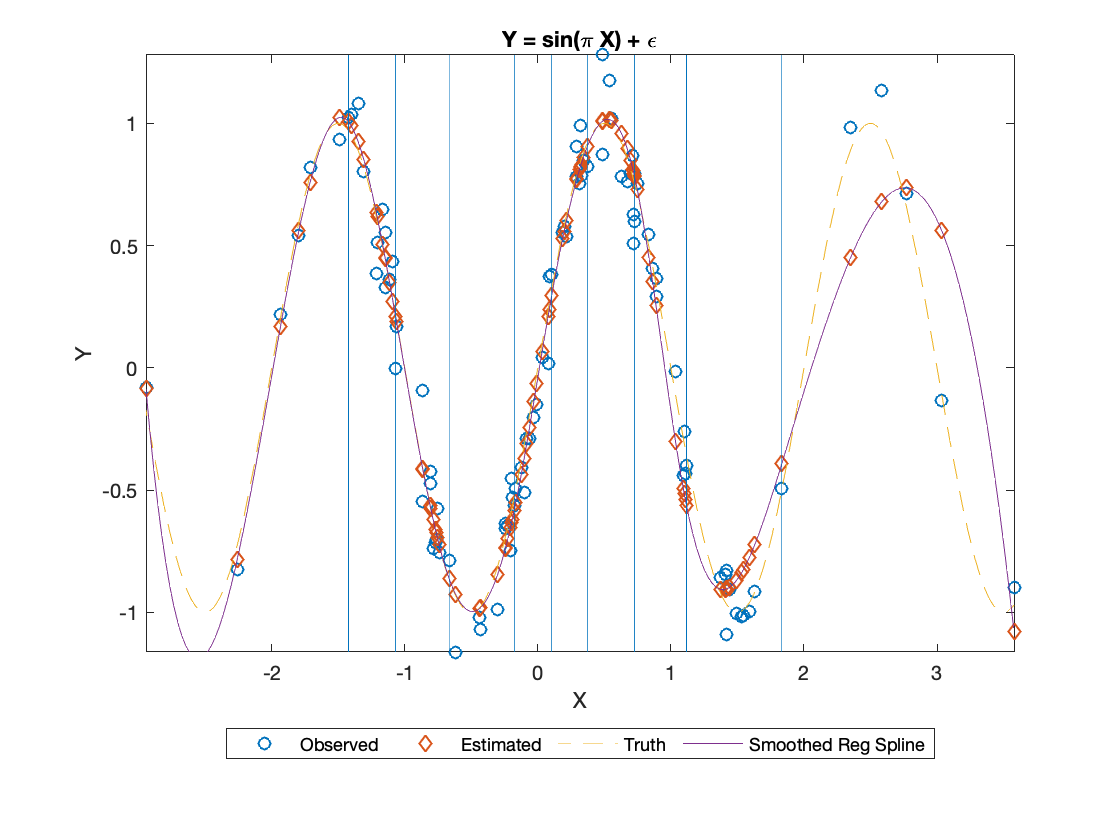

[n k] = size(X);
G = zeros(n,order+n_knots);
for i = 1:order
    G(:,i) = X.^(i-1);
end

for j = 1:n_knots
    G(:,order+j) = subplus(X-knots(j+1)).^(order-1);
end

RS = G*(G'*G)^-1*G';
Y_RS = RS*Y;
beta = (G'*G)^-1*G'*Y;

%for plotting the spline curve
xx = X(1):0.01:X(n);
p = fliplr(beta(1:order)');
yy = polyval(p,xx);
for l = 2:n_knots+1
    pp = mkpp([knots(l) X(n)],[beta(l+order-1) 0 0 0]);
    yy = yy + ppval(pp,xx).*(xx-knots(l)>0);
end

y_limits = [min(min(Y),min(Y_RS)) max(max(Y),max(Y_RS))];
plot(X,Y,'o',X,Y_RS,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-')
for i=2:n_knots+1
    l = line([knots(i) knots(i)], y_limits); 
    set(get(get(l,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
end
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated', 'Truth','Smoothed Reg Spline',...
    'Location','bestoutside','Orientation','horizontal');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,RS,rowNames(5));

### Smoothing Cubic Spline

lambda = 1.0;

like regression spline, but with added omega term


$$||y-G\beta||_2^2 + \lambda\beta^T\Omega\beta \text{, where } G_{ij} = g_j(x_i) \text{ and } \Omega_{jk} = \int g''_j(t)g''_k(t)dt \enspace i,j = 1,...,n$$



$$\hat{\beta} = (G^TG+\lambda\Omega)^{-1}G^Ty$$


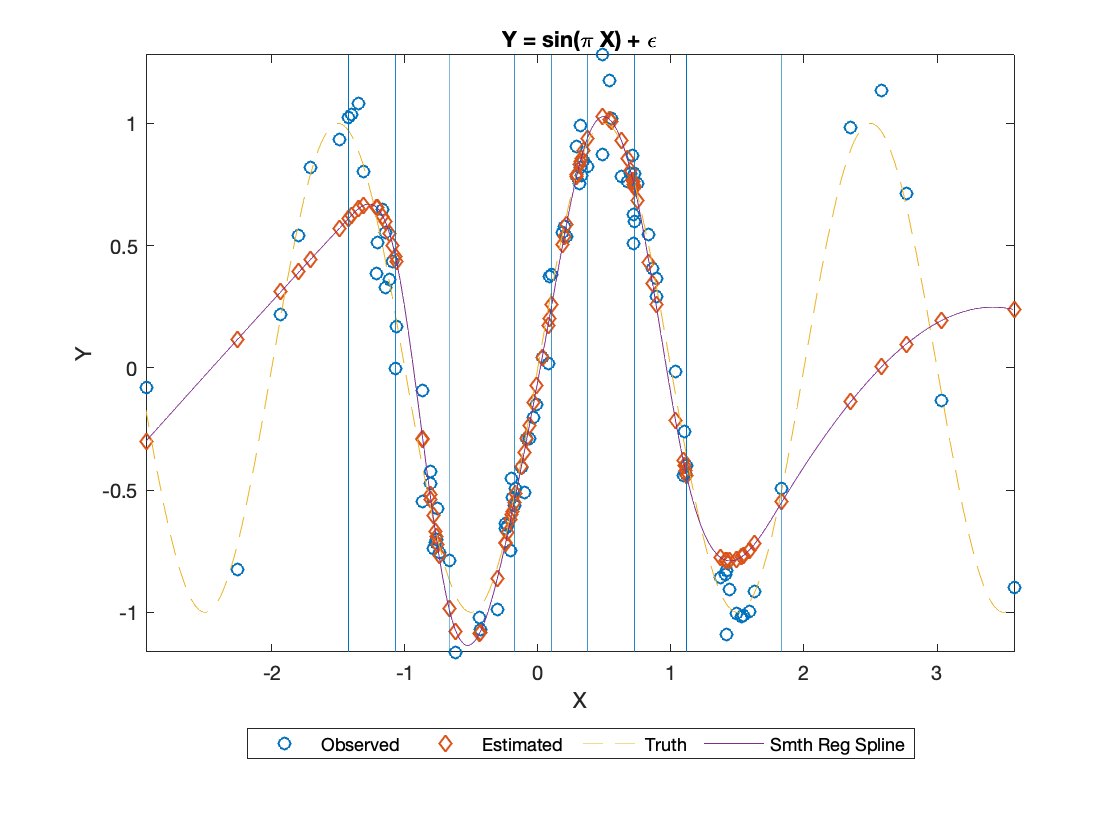

[n k] = size(X);
G = zeros(n,order+n_knots);
for i = 1:order
    G(:,i) = X.^(i-1);  
end
for j = 1:n_knots
    x_l = knots(j+1);
    G(:,order+j) = subplus(X-x_l).^(order-1);
end

basisPoly = [flipud(eye(4)); ones(n_knots,1) ...
    -3*knots(2:end-1) 3*knots(2:end-1).^2 ...
    -knots(2:end-1).^3];

g2Prime = zeros(order+n_knots,order-2);

for k = 1:n_knots+order
    deriv2 = polyder(polyder(basisPoly(k,:)));
    g2Prime(k,:)=[zeros(1,order-2-size(deriv2,2)) deriv2];
end

tempKnots = [repmat(knots(1),order-1,1); knots];
omega = zeros(order+n_knots,order+n_knots);
for l = 1:n_knots+order
    for m= 1:n_knots+order
        p = polyint(conv(g2Prime(l,:),g2Prime(m,:)));
        omega(l,m) = polyval(p,X(end))-polyval(p,X(1))*...
            (tempKnots(l)==X(1))*(tempKnots(m)==X(1));
    end
end

S = G*(G'*G+lambda*omega)^-1*G';
Y_S = S*Y;
beta = (G'*G+lambda*omega)^-1*G'*Y;

%for plotting the spline curve
xx = X(1):0.01:X(end);
p = fliplr(beta(1:order)');
yy = polyval(p,xx);

for l = 2:n_knots+1
    pp = mkpp([knots(l) X(n)],[beta(l+order-1) 0 0 0]);
    yy = yy + ppval(pp,xx).*(xx-knots(l)>0);
end

y_limits = [min(min(Y),min(Y_S)) max(max(Y),max(Y_S))];
plot(X,Y,'o',X,Y_S,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
for i=2:n_knots+1
    l = line([knots(i) knots(i)], y_limits); 
    set(get(get(l,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
end
xlim([X(1) X(end)]);
ylim(y_limits);
legend('Observed','Estimated', 'Truth','Smth Reg Spline',...
    'Location','bestoutside','Orientation','horizontal');
title('Y = sin(\pi X) + \epsilon');
xlabel('X');
ylabel('Y');
hold off;


smoothness = loadSmoothness(smoothness,varNames,S,rowNames(6));

## Interpolating Cubic Splines

Using Atkinson, p 168: $M_i=s''(x_i) \enspace \text{ for }i=1,2,...,n \text{ and } h_i = x_{i+1}-x_i$

$s''(x) = \frac{(x_{i+1}-x)M_i +(x-x_i)M_{i+1}}{h_i}, x_i \le x \le x_{i+1} \enspace 1\le i \le n-1$ and therefore


$$s(x) =  \frac{(x_{i+1}-x)^3M_i +(x-x_i)^3M_{i+1}}{6h_i}+\frac{(x_{i+1}-x)y_i+(x-x_i)y_{i+1}}{h_i} -\frac{h_i}{6}\big((x_{i+1}-x)M_i +(x-x_i)M_{i+1}\big)$$



$$\frac{h_{i-1}}{6}M_{i-1} + \frac{h_{i-1}+h_i}{3}M_i + \frac{h_i}{6}M_{i+1} = \frac{y_{i+1}-y_i}{h_i}-\frac{y_i-y_{i-1}}{h_{i-1}} \text{ for } i=2,3,...,n-1$$


### Not-A-Knot


$$s'''(x) \text{ continuous at }x_2,x_{n-1} 
\rightarrow \frac{M_2-M_1}{h_1}= \frac{M_3-M_2}{h_2} \text{ and }
\frac{M_{n-1}-M_{n-2}}{h_{n-2}}=\frac{M_n-M_{n-1}}{h_{n-1}}$$


[n k] = size(X);
C =  [zeros(n-1,1) eye(n-1)]- [eye(n-1) zeros(n-1,1)];
h = C*X;
h_inv =h.^-1;
D = [zeros(1,n-1);eye(n-1)] + [eye(n-1); zeros(1,n-1)];
D(1,1) = 0;
E = diag(h/6,-1)+ diag(D*h/3)+ diag(h/6,1);
%not-a-knot conditions
E(1,1) = -h_inv(1);
E(1,2) = h_inv(1)+h_inv(2);
E(1,3) = -h_inv(2);
E(1,4:n) = zeros(1,n-3);
E(n,1:n-3) = zeros(1,n-3);
E(n,n-2) = -h_inv(n-2);
E(n,n-1) = h_inv(n-2)+h_inv(n-1);
E(n,n) = -h_inv(n-1);

F = [ zeros(1,n); ...
        [zeros(n-2,2) diag(h_inv(2:end))] ...
        + [diag(h_inv(1:end-1)) zeros(n-2,2)] ...
        - [zeros(n-2,1) diag(h_inv(1:end-1)) zeros(n-2,1)] ...
        - [zeros(n-2,1) diag(h_inv(2:end)) zeros(n-2,1)]; ...
    zeros(1,n)];

M = (E^-1)*F*Y;

need all x as terms of (x-x_i)^p

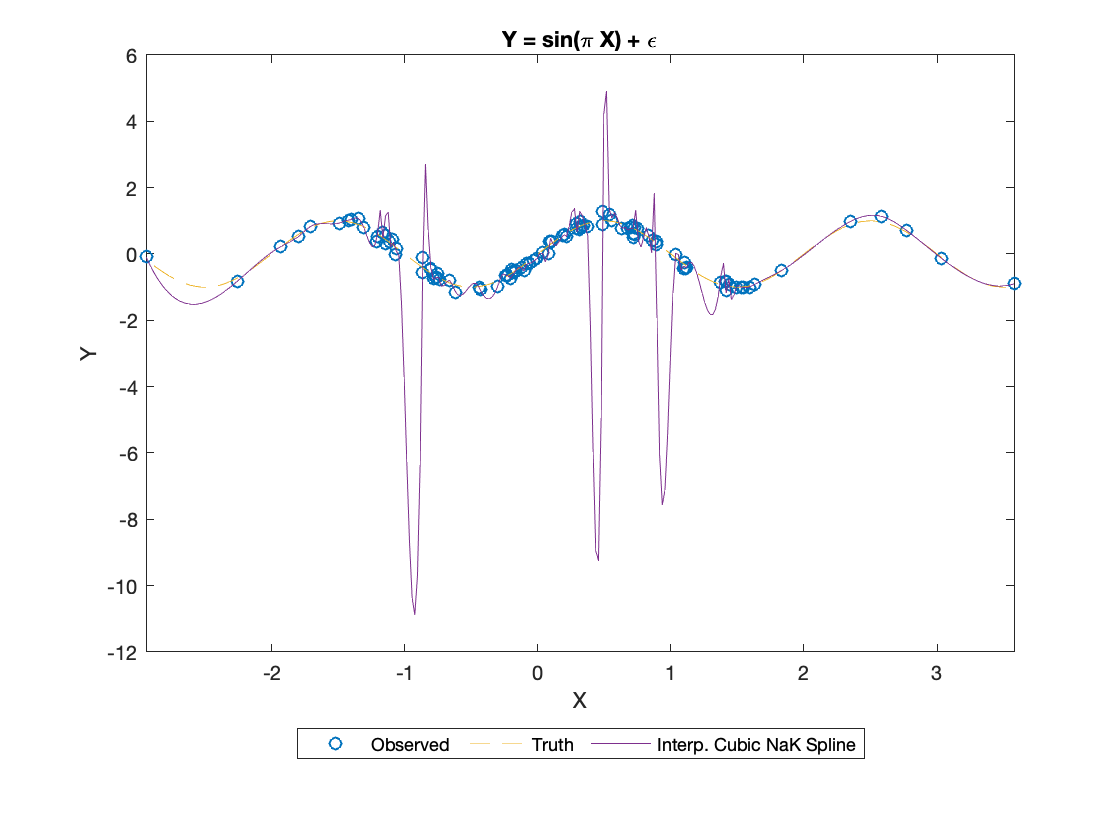

%coefs(i,1)*(X-breaks(i))^(k-1) + coefs(i,2)*(X-breaks(i))^(k-2) + ... + coefs(i,k-1)*(X-breaks(i)) + coefs(i,k).

coefs = zeros(n-1,4);

coefs(:,1) = diag(h_inv)*C*M/6;
coefs(:,2) = M(1:end-1)/2;
C_1 = [zeros(n-1,1) eye(n-1)]+2*[eye(n-1) zeros(n-1,1)];
coefs(:,3) = diag(h_inv)*C*Y-diag(h)*C_1*M/6;
coefs(:,4) = Y(1:end-1);
breaks = X;
pp = mkpp(breaks,coefs);

xx = X(1):0.02:X(end);

plot(X,Y,'o');
hold on;
ax = gca;
ax.ColorOrderIndex = 3;
fplot(@(x) sin(pi*x),'--');
plot(xx,ppval(pp,xx),'-');
title('Y = sin(\pi X) + \epsilon');
legend('Observed', 'Truth','Interp. Cubic NaK Spline',...
    'Location','bestoutside','Orientation','horizontal');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)])
%ylim([min(Y) max(Y)])
hold off;

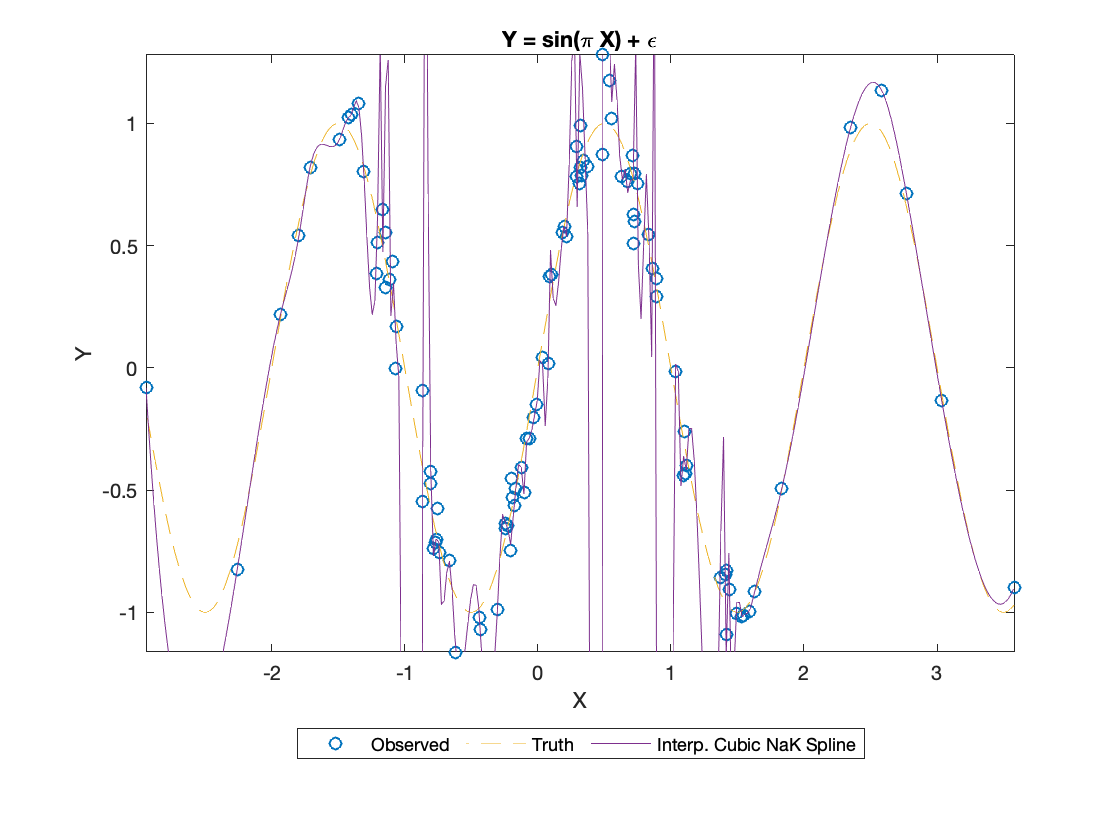


plot(X,Y,'o');
hold on;
ax = gca;
ax.ColorOrderIndex = 3;
fplot(@(x) sin(pi*x),'--');
plot(xx,ppval(pp,xx),'-');
title('Y = sin(\pi X) + \epsilon');
legend('Observed', 'Truth','Interp. Cubic NaK Spline',...
    'Location','bestoutside','Orientation','horizontal');
xlabel('X');
ylabel('Y');
xlim([X(1) X(end)])
ylim([min(Y) max(Y)])
hold off;


smoothness = loadSmoothness(smoothness,varNames,eye(n),rowNames(7));

smoothness(:,varNames(1:end-1))

ans = 7×4 table
                    df_Px     df_Err    df_Var    df_Mx 
                    ______    ______    ______    ______

    linear               1        99         1        99
    affine               2        98         2        98
    NW              5.2092    93.778    4.1963    94.791
    LL              6.9828    92.196    6.1612    93.017
    regSpline           13        87        13        87
    smoothSpline    9.3085    90.431    9.0483    90.691
    interp             100         0       100         0


### Natural 


$$s''(x_1)=0 \text{ and } s''(x_n)=0 \rightarrow M_1=0 \text{ and } M_n=0$$



$$\frac{h_1+h_2}{3}M_2+\frac{h_2}{6}M_3 = \frac{y_3-y_2}{h_2} - \frac{y_2-y_1}{h_1} 
\text{ and } 
\frac{h_{n-2}}{6}M_{n-2} + \frac{h_{n-2}+h_{n-1}}{3}M_{n-1} = \frac{y_{n}-y_{n-1}}{h_{n-1}}-\frac{y_{n-1}-y_{n-2}}{h_{n-2}} $$


[n k] = size(X);
C =  [zeros(n-1,1) eye(n-1)]- [eye(n-1) zeros(n-1,1)];
h = C*X;
h_inv =h.^-1;
D = [zeros(n-2,1) eye(n-2)]+ [eye(n-2) zeros(n-2,1)];
E = diag(h(2:end-1)/6,-1)+ diag(D*h/3)+ diag(h(2:end-1)/6,1);

F = [zeros(n-2,2) diag(h_inv(2:end))]+ [diag(h_inv(1:end-1)) zeros(n-2,2)] ...
    - [zeros(n-2,1) diag(h_inv(1:end-1)) zeros(n-2,1)] ...
    - [zeros(n-2,1) diag(h_inv(2:end)) zeros(n-2,1)] ;

M = [0;(E^-1)*F*Y;0];

need all x as terms of (x-x_i)^p


$$(x_{i+1}-x)^3= \Big( (x_{i+1}-x_i)-(x-x_i)\Big)^3 = -(x-x_i)^3 +3h_i(x-x_i)^2 -3h_i^2(x-x_i) +h_i^3$$



$$s(x)= (x-x_i)^3\Big(\frac{M_{i+1}-M_i}{6h_i} \Big) +

(x-x_i)^2\Big( \frac{M_i}{2}\Big)+

(x-x_i)\Big( \frac{y_{i+1}-y_i}{h_i}-\frac{h_i}{6}(2M_i+M_{i+1})\Big)+

y_i
$$


%coefs(i,1)*(X-breaks(i))^(k-1) + coefs(i,2)*(X-breaks(i))^(k-2) + ... + coefs(i,k-1)*(X-breaks(i)) + coefs(i,k).

coefs = zeros(n-1,4);

coefs(:,1) = diag(h_inv)*C*M/6;
coefs(:,2) = M(1:end-1)/2;
C_1 = [zeros(n-1,1) eye(n-1)]+2*[eye(n-1) zeros(n-1,1)];
coefs(:,3) = diag(h_inv)*C*Y-diag(h)*C_1*M/6;
coefs(:,4) = Y(1:end-1);
breaks = X;
pp = mkpp(breaks,coefs);

% xx = X(1):0.02:X(end);
% plot(X,Y,'o');
% hold on;
% ax = gca;
% ax.ColorOrderIndex = 3;
% fplot(@(x) sin(pi*x),'--');
% plot(xx,ppval(pp,xx),'-');
% title('Y = sin(X) + \epsilon');
% legend('Observed', 'Truth','Interp. Cubic Nat. Spline',...
%     'Location','bestoutside','Orientation','horizontal');
% xlabel('X');
% ylabel('Y');
% xlim([X(1) X(end)])
% ylim([min(Y) max(Y)])
% hold off;

## MATLAB's spline algorithms

keeping for later

% scs = csaps(X,Y);
% fnplt(scs), hold on, plot(X,Y,'o')
% legend('smoothing spline','noisy data'), hold off
% 
% 
% [scs,p] = csaps(X,Y); 
% p
% fnplt(scs), hold on
% fnplt(csaps(X,Y,p/2),'--')
% fnplt(csaps(X,Y,(1+p)/2),':'), plot(X,Y,'o')
% legend('smoothing spline','more smoothed','less smoothed',...
%     'noisy data'), hold off

## Helper Functions

function tab = loadSmoothness(tab,vars,mat,rowName)
    tab(rowName,vars(1)) = {trace(mat)};
    tab(rowName,vars(2)) = {size(mat,1) - trace(2*mat -mat*mat')};
    tab(rowName,vars(3)) = {trace(mat*mat')};
    tab(rowName,vars(4)) = {size(mat,1) - trace(mat)};
    tab(rowName,vars(5)) = {norm(mat)*norm(mat^-1)};    
end

## Specification help

Nadaraya-Watson: [https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf](https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf) and [http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf](http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf) (cause I can't put my hands on the notes from Fall 2017)

Local linear: [http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf](http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf)

Splines: [http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf,](http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf,)  [http://www.stat.columbia.edu/~madigan/DM08/regularization.ppt.pdf,](http://www.stat.columbia.edu/~madigan/DM08/regularization.ppt.pdf,) and [http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf](http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf)